### Plotting Fig.S4c-f 

### Determine the four parameters: t_dip, t_e, n, tau

clc;clear

#### Plot Fig.S4c

Each row corresponds to values of $F\left(\phi ,\eta =0\right)$, where $\phi =0:\frac{\pi }{4}:2\pi$. 

Different rows denote different values of $t_{\textrm{dip}}$

load S_c.mat
L=8;
noise_std=6.5*1e-4; %Approximated value of the standard error of the noise, estimated from the FID.

[Ratio,Ratio_std]=CalculateRatio(S,L,noise_std);
Ratio

Ratio =     1.1424    1.4419    1.5043    1.5081    1.5048    1.5118    1.5046    1.5056    1.5101


F00=S(:,1)'

F00 =     1.0077    0.9857    1.0032    1.0004    0.9980    0.9975    0.9984    0.9974    0.9972


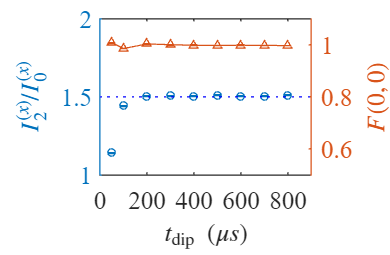

t_dip_seq=[50,100:100:800]; %in us

x=t_dip_seq;

figure()
yyaxis right
error_bar=1.96*noise_std*ones(1,length(x));
errorbar(x,F00,error_bar,'-^','MarkerSize',3,'CapSize',3)
xlabel('$t_{\mathrm{th}}\ (\mu s)$')
ylabel('$F(0,0)$','Interpreter','latex')
ylim([0.5 1.1])
yticks(0.6:0.2:1)

yyaxis left
error_bar=1.96*Ratio_std;
errorbar(x,Ratio,error_bar,'o','MarkerSize',3,'CapSize',3)
hold on
plot([0,900],[1.5,1.5],'b:')
xlabel('$t_{\mathrm{dip}}\ (\mu s)$','Interpreter','latex')
ylabel('$I_2^{(x)}/I_0^{(x)}$','Interpreter','latex')

ylim([1 2])

xlim([0 900])
xticks(0:200:800)

fontsize(gcf,10,'points')
fontname(gcf,"Times New Roman")
set(gcf,'unit','centimeters','position',[10,10,5.5,3.6]);

#### Plot Fig.S4d

Each row corresponds to values of $F\left(\phi ,\eta =0\right)$, where $\phi =0:\frac{\pi }{4}:2\pi$. 

Different rows denote different values of $t_e$

load S_d.mat
L=8;
noise_std=6.5*1e-4; %Approximated value of the standard error of the noise, estimated from the FID.

[Ratio,Ratio_std]=CalculateRatio(S,L,noise_std);
Ratio

Ratio =     1.5112    1.5056    1.5035    1.5113    1.5074    1.5082    1.5148


F00=S(:,1)'

F00 =     0.5217    0.7972    0.9594    1.0000    0.9293    0.7772    0.5811


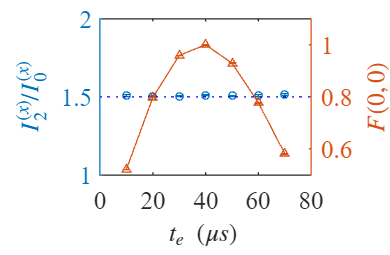

t_e_seq=[10:10:70]; %in us

x=t_e_seq;

figure()
yyaxis right
error_bar=1.96*noise_std*ones(1,length(x));
errorbar(x,F00,error_bar,'-^','MarkerSize',3,'CapSize',3)
ylabel('$F(0,0)$','Interpreter','latex')
ylim([0.5 1.1])
yticks(0.6:0.2:1)

yyaxis left
error_bar=1.96*Ratio_std;
errorbar(x,Ratio,error_bar,'o','MarkerSize',3,'CapSize',3)
hold on
plot([0,80],[1.5,1.5],'b:')
xlabel('$t_e\ (\mu s)$ ','Interpreter','latex')
xlim([0 80])
xticks(0:20:80)

ylim([1 2])

ylabel('$I_2^{(x)}/I_0^{(x)}$','Interpreter','latex')
fontsize(gcf,10,'points')
fontname(gcf,"Times New Roman")
set(gcf,'unit','centimeters','position',[10,10,5.5,3.6]);

#### Plot Fig.S4e

Each row corresponds to values of $F\left(\phi ,\eta =0\right)$, where $\phi =0:\frac{\pi }{8}:2\pi$. 

Different rows denote different values of $n$

clear;clc
load S_e.mat
L=16;
noise_std=6.5*1e-4; %Approximated value of the standard error of the noise, estimated from the FID.

[Ratio,Ratio_std]=CalculateRatio(S,L,noise_std);
Ratio

Ratio =     1.6858    1.4215    1.5730    1.5564    1.5000    1.4880    1.4648    1.4895    1.4725


F00=S(:,1)'

F00 =     1.0817    1.0363    1.0235    0.9916    0.9707    0.9714    0.9688    0.9680    0.9506


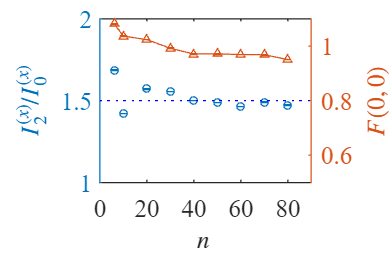


loop_seq=[6,10,20:10:80];
x=loop_seq;

figure()
yyaxis right

error_bar=1.96*noise_std*ones(1,length(x));
errorbar(x,S(:,1),error_bar,'-^','MarkerSize',3,'CapSize',3)
xlabel('$n$')
ylabel('$F(0,0)$','Interpreter','latex')
ylim([0.5 1.1])
yticks(0.6:0.2:1)

yyaxis left
error_bar=1.96*Ratio_std;
errorbar(x,Ratio,error_bar,'o','MarkerSize',3,'CapSize',3)
hold on
plot([0,90],[1.5,1.5],'b:')
xlabel('$n$ ','Interpreter','latex')
ylabel('$I_2^{(x)}/I_0^{(x)}$','Interpreter','latex')

ylim([1 2])

xlim([0 90])
xticks(0:20:80)

fontsize(gcf,10,'points')
fontname(gcf,"Times New Roman")
set(gcf,'unit','centimeters','position',[10,10,5.5,3.6]);

#### Plot Fig.S4f

Using 400mas4_liyuchen_20240331_Determinetau2_ada_H1

Each row corresponds to values of $F\left(\phi ,\eta =0\right)$, where $\phi =0:\frac{\pi }{4}:2\pi$. 

Different rows denote different values of $\tau \;$

clear;clc
load S_f.mat
L=8;
noise_std=6.2*1e-4; %estimated from the FID.

[Ratio,Ratio_std]=CalculateRatio(S,L,noise_std);
Ratio

Ratio =     0.8318    0.9237    0.9779    1.0908    1.1955    1.2178    1.2796    1.2935    1.3338    1.3908    1.4028    1.4348    1.4205    1.4533    1.5013    1.5125    1.5222    1.5294    1.5543


F00=S(:,1)'

F00 =     0.8308    0.8730    0.8820    0.9123    0.9332    0.9416    0.9505    0.9505    0.9655    0.9778    0.9689    0.9711    0.9724    0.9834    0.9910    0.9964    0.9997    0.9910    0.9947


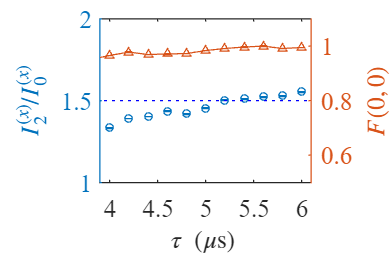


tau_seq=[2.4:0.2:6]; %in us
x=tau_seq;

figure()
yyaxis right

error_bar=1.96*noise_std*ones(1,length(x));
errorbar(x,F00,error_bar,'-^','MarkerSize',3,'CapSize',3)
xlabel('$t_{\mathrm{th}}\ (\mu s)$')
ylabel('$F(0,0)$','Interpreter','latex')
ylim([0.5 1.1])
yticks(0.6:0.2:1)

yyaxis left
error_bar=1.96*Ratio_std;
errorbar(x,Ratio,error_bar,'o','MarkerSize',3,'CapSize',3)
hold on
plot([0,11],[1.5,1.5],'b:')
xlabel('$\tau\ (\mathrm{\mu s})$ ','Interpreter','latex')
ylabel('$I_2^{(x)}/I_0^{(x)}$','Interpreter','latex')

ylim([1 2])

xlim([3.9 6.1])
xticks(4:0.5:6)

fontsize(gcf,10,'points')
fontname(gcf,"Times New Roman")
set(gcf,'unit','centimeters','position',[10,10,5.5,3.6]);

function [Ratio,Ratio_std]=CalculateRatio(S,L,noise_std)

RealPart=real(fftshift(fft(S,L,2)/L,2));

ZeroOrder=RealPart(:,L/2+1);
DoubleOrder=RealPart(:,L/2+1-2);

Ratio=(DoubleOrder./ZeroOrder)';
var_Double=noise_std^2/2/L;
var_Zero=noise_std^2/L;
Ratio_std=sqrt(var_Double./(ZeroOrder.^2)+var_Zero*(DoubleOrder.^2)./(ZeroOrder.^4));
end